# Stubbornness in the Friedkin-Johnsen model

Four experiments, selected from the exploratory notebook ch05_stubborness_v1, one for each of the questions below. Reference: Proskurnikov & Tempo, Part I, section 6; notation as in Chapter 4. Opinions are scalar throughout.

- What does stubbornness change compared with classical averaging?

- What does the AMOUNT of stubbornness change?

- What happens with one prejudiced agent, and with several?

- How does the network structure decide where these effects propagate?

The last section lists what is still open. The notebook is deliberately not a complete treatment of the Friedkin-Johnsen theory.

projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 1. The two models, and the network used in Experiments 1-3

French-DeGroot is pure averaging, x(k+1) = W x(k), with W row-stochastic. Friedkin-Johnsen adds one term:

          x(k+1) = Lambda W x(k) + (I - Lambda) u                    (M4.1)

Lambda = diag(lambda_i) holds each agents susceptibility to social influence, u is the vector of prejudices - pre-existing opinions formed outside the discussion - and 1 - lambda_i is the weight of the anchor, re-applied at EVERY step. With lambda_i = 1 for all i the anchor vanishes and (M4.1) IS French-DeGroot; with lambda_i = 0 agent i sits at u_i. Such an agent is called prejudiced, and stubborn in Part Is strict sense only if also u_i = x_i(0).

The network is a line of five agents, each listening to itself and its neighbours. Two properties are deliberate: it is rooted and aperiodic, so DeGroot genuinely converges on it and section 2 is not just showing periodicity; and it is strongly connected, the hypothesis Corollary 4.1 needs in sections 3 and 4. The prejudices put the two ends at opposite poles, and x(0) is unrelated to u so that u = x(0) is never assumed by accident.

n = 5;
A = [1 1 0 0 0        % 1 listens to itself and 2
     1 1 1 0 0        % 2 listens to 1, itself, 3
     0 1 1 1 0        % 3 listens to 2, itself, 4
     0 0 1 1 1        % 4 listens to 3, itself, 5
     0 0 0 1 1];      % 5 listens to 4 and itself
W = row_stochastic(A);

u  = [ 1;  0;  0;  0; -1];      % prejudices: the two ends pull in opposite directions
x0 = [ 0;  2; -2;  3;  1];      % initial opinions, unrelated to u on purpose

p = social_power(W);
fprintf('rooted %d | period %d | DeGroot reaches consensus %d | p''x(0) = %.4f\n', ...
    graph_summary(W).rooted, graph_period(W), graph_summary(W).consensus, p.'*x0);

rooted 1 | period 1 | DeGroot reaches consensus 1 | p'x(0) = 0.8462


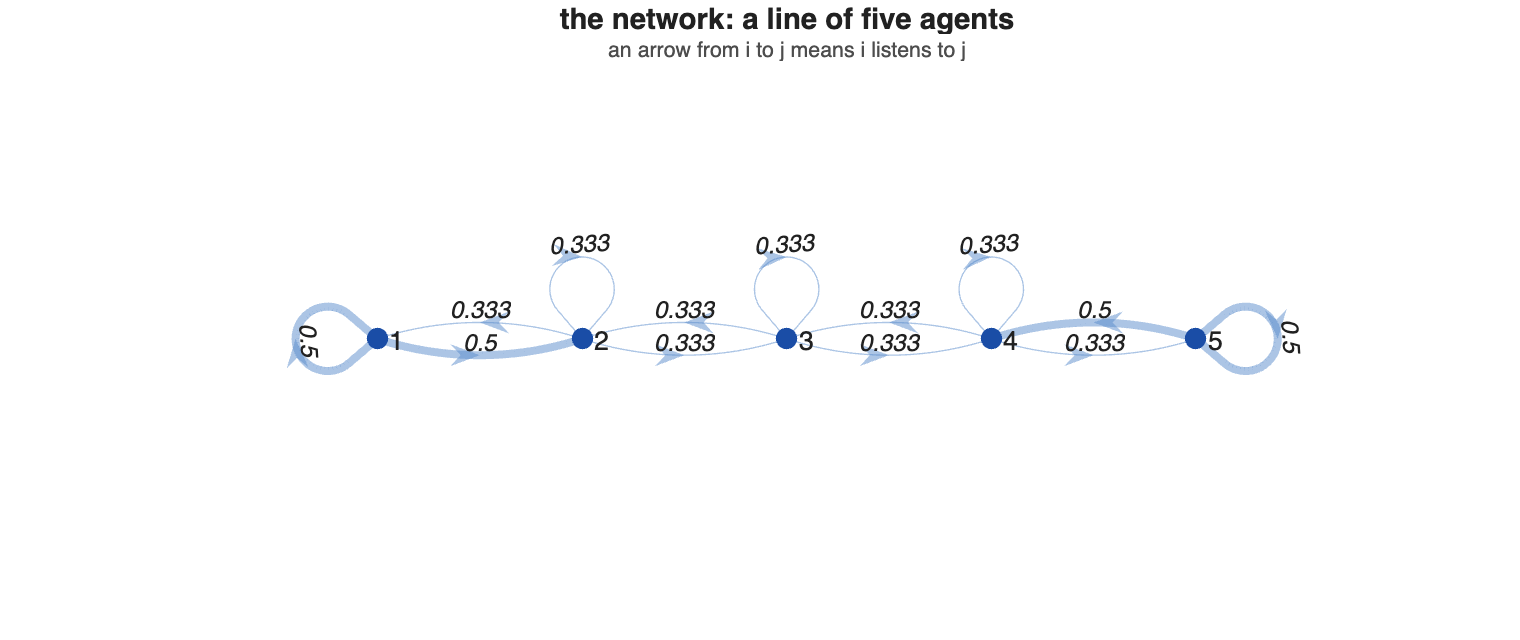


figure('Position',[0 0 760 320]);
plot_graph(W, [], 'Layout', [(1:5).' zeros(5,1)], ...
    'Title','the network: a line of five agents', ...
    'Subtitle','an arrow from i to j means i listens to j')

## 2. What stubbornness changes

QUESTION. Same network, same initial opinions: what does the anchoring term do to the outcome?

SETUP. Both models on the same W and the same x(0), with lambda_i = 0.8 for every agent - so nobody is frozen, everybody is genuinely listening, and the prejudice term is the only difference between the two runs.

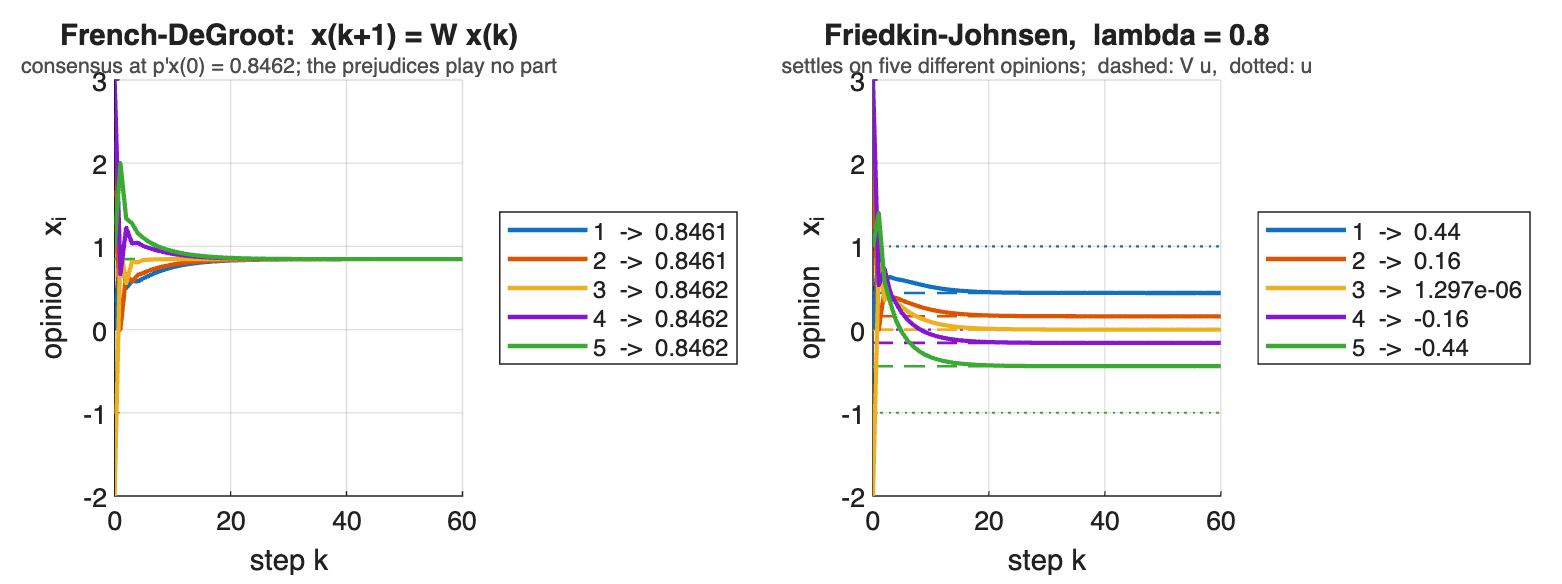

lam = 0.8 * ones(n,1);
Xd  = sim_degroot(W, x0, 60);
Xf  = sim_friedkin_johnsen(W, lam, u, x0, 60);

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(Xd, [], 'Limit', limit_matrix(W)*x0, ...
    'Title','French-DeGroot:  x(k+1) = W x(k)', ...
    'Subtitle','consensus at p''x(0) = 0.8462; the prejudices play no part');
nexttile;
plot_opinions(Xf, [], 'Limit', fj_equilibrium(W, lam, u), 'Prejudice', u, ...
    'Title','Friedkin-Johnsen,  lambda = 0.8', ...
    'Subtitle','settles on five different opinions;  dashed: V u,  dotted: u');


% the same statement as numbers
fprintf('rank(lim W^k) = %d   -> one number, the same for everyone\n', rank(limit_matrix(W)));

rank(lim W^k) = 1   -> one number, the same for everyone


fprintf('rank(V)       = %d   -> n numbers, one per agent\n', rank(total_influence(W, lam)));

rank(V)       = 5   -> n numbers, one per agent


for xt = {x0, [10;10;10;10;10]}
    Ld = sim_degroot(W, xt{1}, 400);
    Lf = sim_friedkin_johnsen(W, lam, u, xt{1}, 400);
    fprintf('x(0) = %-18s  DeGroot -> %7.4f (all)   FJ -> %s\n', ...
        mat2str(xt{1}.'), Ld(1,end), mat2str(round(Lf(:,end).', 4)));
end

x(0) = [0 2 -2 3 1]        DeGroot ->  0.8462 (all)   FJ -> [0.44 0.16 0 -0.16 -0.44]
x(0) = [10 10 10 10 10]    DeGroot -> 10.0000 (all)   FJ -> [0.44 0.16 0 -0.16 -0.44]


WHAT THE FIGURE SHOWS. In DeGroot every update is a convex combination of the current opinions, so the spread can only shrink; on this graph it shrinks to zero and the group agrees, at the social-power-weighted average of x(0). In FJ each agent re-injects its own prejudice at every step, so the averaging works against a pull that never decays: the group still converges, but to five different values. The disagreement is not a failure to converge and not a broken network - the network is strongly connected and everybody keeps listening forever.

CONNECTION TO THEORY. The two limits come from operators of different RANK. DeGroot gives lim W^k = 1 p, rank one: the state collapses onto one direction, so only agreement is reachable. FJ gives x(inf) = V u with V = (I - Lambda W)^-1 (I - Lambda), here full rank, so each agent keeps a trace of its own prejudice. Both are row-stochastic (Theorem 4.1), which is why the disagreement is bounded - inside the convex hull of the prejudices, never runaway. The printed lines add the rest: two very different x(0) give the same FJ limit but different DeGroot limits, so FJ remembers only what anchors it.

## 3. The effect of the amount of stubbornness

QUESTION. The network and the prejudices are fixed. What does the size of lambda change?

SETUP. Lambda = lambda I, so one number describes the whole group. Four representative values, each with a horizon matched to its own decay rate.

fprintf(' lambda   rho(Lambda W)   spread of x(inf)\n');

 lambda   rho(Lambda W)   spread of x(inf)


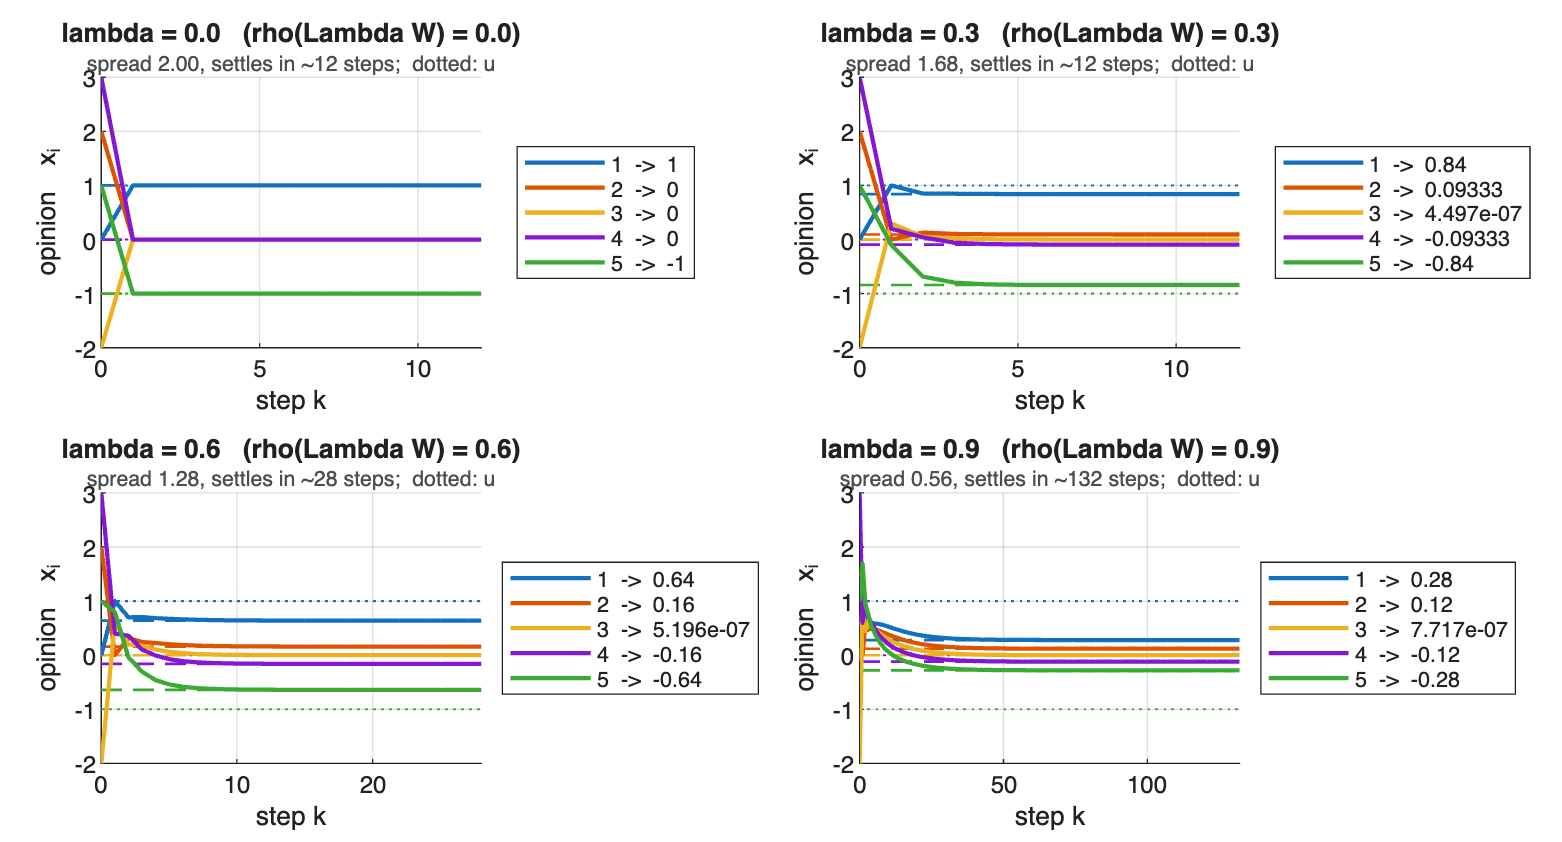

   0.0        0.00            2.0000
   0.3        0.30            1.6800
   0.6        0.60            1.2800
   0.9        0.90            0.5600


figure('Position',[0 0 1150 620]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');
for l = [0 0.3 0.6 0.9]
    lamh = l * ones(n,1);
    xi   = fj_equilibrium(W, lamh, u);
    Kl   = max(12, min(300, ceil(log(1e-6)/log(max(l, 1e-3)))));
    X    = sim_friedkin_johnsen(W, lamh, u, x0, Kl);
    fprintf('   %.1f        %.2f            %.4f\n', l, max(abs(eig(l*W))), max(xi)-min(xi));
    nexttile;
    plot_opinions(X, [], 'Limit', xi, 'Prejudice', u, ...
        'Title', sprintf('lambda = %.1f   (rho(Lambda W) = %.1f)', l, l), ...
        'Subtitle', sprintf('spread %.2f, settles in ~%d steps;  dotted: u', max(xi)-min(xi), Kl));
end

WHAT THE FIGURE SHOWS. At lambda = 0 nobody listens and every agent stays on its own prejudice, spread 2.00. As lambda rises the averaging gains weight against the anchors and the final spread falls - 2.00, 1.68, 1.28, 0.56 - while the trajectories take visibly longer to settle. At lambda = 1 the anchor would be gone altogether and the model would be DeGroot again.

CONNECTION TO THEORY. W row-stochastic gives rho(W) = 1, so for uniform Lambda rho(Lambda W) = lambda exactly. That one number decides everything: below 1 for every lambda < 1, which is why the model converges and at rate lambda, and equal to 1 exactly at lambda = 1, where the eigenvalue 1 of W returns and brings the consensus mode with it. Susceptibility is therefore a trade-off: more of it buys agreement and pays with speed.

## 4. One prejudiced agent, or several

QUESTION. So far every agent was prejudiced. What changes if only one or two are anchored, and the rest simply average?

SETUP. Same network and same u. Only the named agents have lambda_i = 0.5; all the others have lambda_i = 1, i.e. pure DeGroot behaviour. Since the graph is strongly connected and Lambda is not the identity, Corollary 4.1 applies in both cases, so both are asymptotically stable and x(inf) = V u.

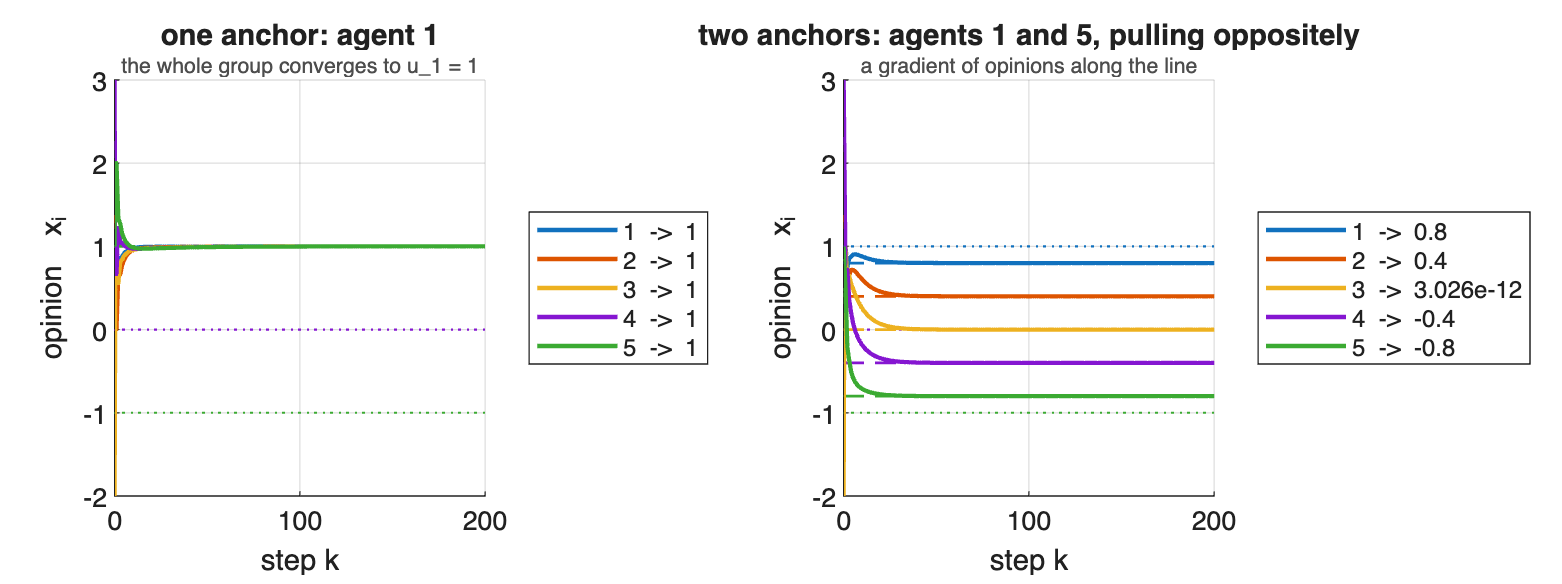

lam1 = ones(n,1);  lam1(1)     = 0.5;      % only agent 1 anchored, at u_1 = +1
lam2 = ones(n,1);  lam2([1 5]) = 0.5;      % agents 1 and 5 anchored, at +1 and -1

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(sim_friedkin_johnsen(W, lam1, u, x0, 200), [], ...
    'Limit', fj_equilibrium(W, lam1, u), 'Prejudice', u, ...
    'Title','one anchor: agent 1', 'Subtitle','the whole group converges to u_1 = 1');
nexttile;
plot_opinions(sim_friedkin_johnsen(W, lam2, u, x0, 200), [], ...
    'Limit', fj_equilibrium(W, lam2, u), 'Prejudice', u, ...
    'Title','two anchors: agents 1 and 5, pulling oppositely', ...
    'Subtitle','a gradient of opinions along the line');


V1 = total_influence(W, lam1)

V1 =     1.0000         0         0         0         0
    1.0000         0         0         0         0
    1.0000         0         0         0         0
    1.0000         0         0         0         0
    1.0000         0         0         0         0


V2 = total_influence(W, lam2)

V2 =     0.9000         0         0         0    0.1000
    0.7000         0         0         0    0.3000
    0.5000         0         0         0    0.5000
    0.3000         0         0         0    0.7000
    0.1000         0         0         0    0.9000


fprintf('one anchor : x(inf) = %s\n', mat2str(round(fj_equilibrium(W, lam1, u).', 4)));

one anchor : x(inf) = [1 1 1 1 1]


fprintf('two anchors: x(inf) = %s\n', mat2str(round(fj_equilibrium(W, lam2, u).', 4)));

two anchors: x(inf) = [0.8 0.4 0 -0.4 -0.8]


WHAT THE FIGURE SHOWS. A single anchored agent does NOT produce disagreement: the whole group converges to u_1 = 1. What it changes is WHICH consensus is reached - DeGroot would have given a weighted average of everybodys initial opinions, whereas here the group ends on agent 1s prejudice and the initial opinions are erased. With two anchors pulling oppositely the group settles on a gradient, 0.8 / 0.4 / 0 / -0.4 / -0.8, each agent sitting between the two prejudices.

CONNECTION TO THEORY. The matrices show the mechanism. (I - Lambda) has one non-zero row per prejudiced agent, so V has one non-zero COLUMN per prejudiced agent. With one anchor V is row-stochastic with a single non-zero column, hence V = 1 e_1 exactly - the consensus in the left panel. With two anchors each row of V is a pair of weights summing to one (0.9/0.1, 0.7/0.3, 0.5/0.5, ...), and those weights are how much of each prejudice the agent absorbs, ordered by its position along the line. So disagreement needs at least two DIFFERENT prejudices, and the network decides how influence is split between them.

## 5. Network structure, and when the model is stable

QUESTION. Experiments 2-4 all relied on the prejudices being able to reach every agent. What happens when they cannot?

SETUP. Two triangles, each internally complete with self-loops, joined by exactly ONE bridge edge; agents 1 and 2 are prejudiced, both in the left triangle, with opposite prejudices. The two cases differ only in the DIRECTION of that edge. Convention: W(i,j) > 0 means i listens to j, and a prejudice travels along the arrows, so agent i is P-dependent when a walk i -> ... -> j reaches a prejudiced j. (Part I draws the arrows the other way and states the same condition as "a walk from j to i".)

base = zeros(6);
base(1,[1 2 3]) = 1;  base(2,[1 2 3]) = 1;  base(3,[1 2 3]) = 1;   % group A: 1,2,3
base(4,[4 5 6]) = 1;  base(5,[4 5 6]) = 1;  base(6,[4 5 6]) = 1;   % group B: 4,5,6

GA = base;  GA(4,1) = 1;                    % B listens to A   (agent 4 listens to agent 1)
GB = base;  GB(1,4) = 1;                    % A listens to B   (agent 1 listens to agent 4)
topo = {'A: B listens to A', row_stochastic(GA); ...
        'B: A listens to B', row_stochastic(GB)};

lamT = [0.5; 0.5; 1; 1; 1; 1];              % agents 1 and 2 prejudiced
uT   = [  1;  -1; 0; 0; 0; 0];              % pulling in opposite directions
x0T  = [  0;   0; 0; 6; 4; 2];              % group B starts far from A
posT = [0 1; 0 -1; -1.2 0; 3 1; 3 -1; 4.2 0];

figure('Position',[0 0 1200 740]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    plot_graph(topo{k,2}, [], 'Layout', posT, 'Weights', false, ...
        'NodeValue', double(lamT < 1), 'NodeName','prejudiced', ...
        'Title', topo{k,1}, 'Subtitle','agents 1 and 2 (left, yellow) are the prejudiced ones');
    colorbar(gca, 'off');                    % the 0/1 scale adds nothing here
end
fprintf('%-20s %-14s %-10s %-12s %-7s %s\n', 'case', 'P-independent', 'rho(LW)', 'rho(L11W11)', ...
    'stable', 'limit depends on x(0)');

case                 P-independent  rho(LW)    rho(L11W11)  stable  limit depends on x(0)


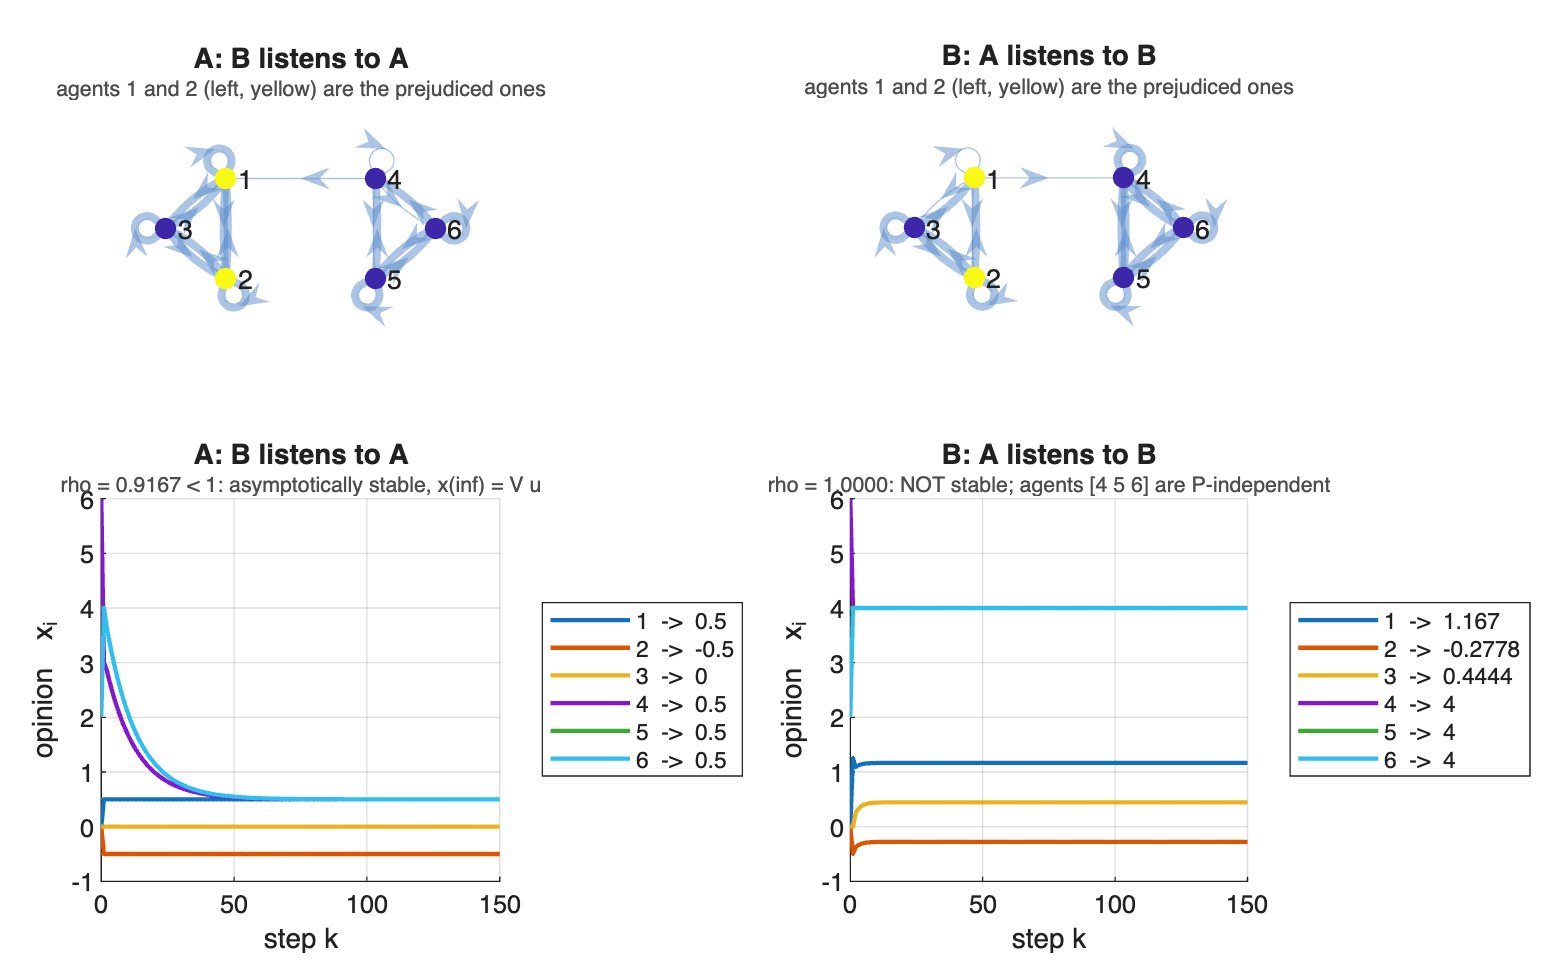

A: B listens to A    (none)         0.9167     0.9167       1       0
B: A listens to B    [4 5 6]        1.0000     0.6250       0       1


for k = 1:2
    Wk = topo{k,2};  r = fj_report(Wk, lamT);
    X  = sim_friedkin_johnsen(Wk, lamT, uT, x0T, 400);
    X2 = sim_friedkin_johnsen(Wk, lamT, uT, x0T - [0;0;0;8;8;8], 400);
    pitxt = mat2str(find(~r.pdependent).');  if r.r == 6, pitxt = '(none)'; end
    fprintf('%-20s %-14s %-10.4f %-12.4f %-7d %d\n', topo{k,1}, pitxt, r.rho, r.rho11, ...
        r.stable, max(abs(X(:,end)-X2(:,end))) > 1e-6);
    nexttile;
    if r.stable
        plot_opinions(X(:,1:151), [], 'Limit', fj_equilibrium(Wk, lamT, uT), ...
            'Title', topo{k,1}, 'Subtitle', sprintf( ...
            'rho = %.4f < 1: asymptotically stable, x(inf) = V u', r.rho));
    else
        plot_opinions(X(:,1:151), [], 'Title', topo{k,1}, 'Subtitle', sprintf( ...
            'rho = %.4f: NOT stable; agents %s are P-independent', r.rho, mat2str(find(~r.pdependent).')));
    end
end

WHAT THE FIGURE SHOWS. In case A the bridge lets group B listen to group A, so the prejudices reach everybody and the whole network settles between the two anchors, at a limit that does not depend on x(0). Reversing that one edge gives case B: now nobody in group B listens to anybody in group A, so the prejudices never enter their updates. Group B runs an ordinary DeGroot model among itself, reaches its own consensus at 4, and DRAGS group A with it - the prejudiced agents no longer control the outcome, and the initial opinions are back in the answer.

CONNECTION TO THEORY. Part I splits the agents into P-dependent ones, which some prejudice reaches, and P-independent (oblivious) ones, which none does; Corollary 4.1 says the model is asymptotically stable IF AND ONLY IF every agent is P-dependent. The table shows exactly that: rho(Lambda W) = 0.9167 in case A and exactly 1 in case B, with the limit independent of x(0) only in case A. Note also rho(Lambda11 W11) = 0.625 in case B - by Theorem 4.1 the P-dependent block is stable on its own whatever the rest does, so all the instability lives in the oblivious block. This mirrors the consensus condition in DeGroot: for consensus one agent must reach everybody, for stability the set of anchors must.

## 6. What I take from this

- FJ is DeGroot plus a constant pull towards a pre-existing opinion, re-applied at every step. lambda_i = 1 recovers DeGroot exactly; lambda_i = 0 pins the agent to u_i.

- That term is what makes persistent disagreement possible. Averaging can only shrink the spread, so its limit operator has rank one and only consensus is reachable; the FJ limit operator V has full rank and is row-stochastic, so the disagreement is persistent but bounded.

- The size of lambda is a trade-off, not a free parameter: rho(Lambda W) = lambda for a uniform Lambda, so more susceptibility means less final disagreement and slower convergence.

- Disagreement requires at least two anchors with DIFFERENT prejudices; one anchor alone still gives consensus, at its own prejudice. The network decides how the influence of several anchors is split, through the rows of V.

- A prejudice only controls the agents it can reach. The model is asymptotically stable exactly when every agent is P-dependent; otherwise rho(Lambda W) = 1, the oblivious block runs its own DeGroot dynamics and drags the rest, and x(0) reappears in the limit.

## 7. Possible directions from here

Questions raised by the experiments above, rather than results. Any of them could be the next step.

- HETEROGENEOUS STUBBORNNESS. Experiment 3 used a single lambda for everyone. Does the average susceptibility of a group determine the outcome, or does the POSITION of the stubborn agents matter more? A first informal check suggested the latter, which would be worth doing properly.

- DISTRIBUTION OF PREJUDICES. Experiment 4 placed two anchors at the ends of a line and got a linear gradient. How does the equilibrium depend on where the anchors sit, and how sensitive is it to u?

- INFLUENCE OF PREJUDICED AGENTS. The rows of V say how much of each prejudice each agent absorbs. Is there a useful notion of centrality for anchors - which agent, if anchored, moves the group most?

- STABILITY BOUNDARY. rho(Lambda W) reaches 1 exactly when oblivious agents appear. How does the convergence rate degrade as a network approaches that boundary, and what does the transition look like numerically?

- P-DEPENDENT STRUCTURE. Experiment 5 used one edge to flip a whole group between P-dependent and P-independent. On larger or random graphs, how large does the oblivious block typically get, and how much does it distort the equilibrium of the agents that ARE anchored?

Not covered here at all, and probably later: the multidimensional model of Parsegov et al., and the gossip version in Part II where opinions stop converging pointwise and only their time averages reproduce x(inf).